% filepath: tests/test_step_zzy.mlx
%% 测试 step_zzy 函数的数值精度
% 与 MATLAB 内置 step 函数对比，绘制误差分布

clear; clc;

%% 测试1: 一阶系统
fprintf('========== 测试1: 一阶系统 ==========\n');

========== 测试1: 一阶系统 ==========


num1 = 1;
den1 = [1 2];  % G(s) = 1/(s+2)

% MATLAB 内置函数
sys_matlab = tf(num1, den1);
t_sim = 0:0.01:5;  % 使用统一的时间序列
[y_matlab, t_matlab] = step(sys_matlab, t_sim);

% 自定义实现
sys_zzy = tf_zzy(num1, den1);
[y_zzy, t_zzy] = step_zzy(sys_zzy, 5);

% 对齐到相同时间点
y_zzy_interp = interp1(t_zzy, y_zzy, t_matlab, 'linear', 'extrap');

% 精度验证
abs_error1 = abs(y_matlab - y_zzy_interp);
mse1 = mean(abs_error1.^2);
mae1 = mean(abs_error1);
max_error1 = max(abs_error1);

% 定位最大误差点
[~, idx_max1] = max(abs_error1);
fprintf('最大误差: %.2e (发生在 t=%.2f s)\n', max_error1, t_matlab(idx_max1));

最大误差: 2.78e-16 (发生在 t=0.35 s)


fprintf('MSE: %.2e\n', mse1);

MSE: 1.04e-32


fprintf('MAE: %.2e\n', mae1);

MAE: 7.80e-17



% 初始瞬态区分析（0-0.5秒）
idx_transient1 = t_matlab <= 0.5;
transient_error1 = abs_error1(idx_transient1);
fprintf('初始瞬态区(0-0.5s)最大误差: %.2e\n', max(transient_error1));

初始瞬态区(0-0.5s)最大误差: 2.78e-16



% 稳态区分析（最后1秒）
idx_steady1 = t_matlab >= (max(t_matlab)-1);
steady_error1 = abs_error1(idx_steady1);
fprintf('稳态区误差均值: %.2e\n\n', mean(steady_error1));

稳态区误差均值: 2.31e-17



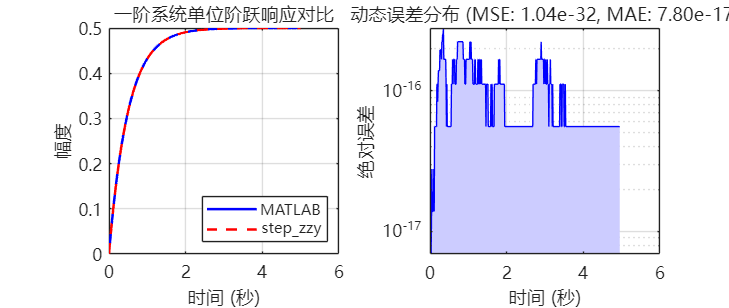


% 动态特性对比图
figure('Name','测试1: 一阶系统', 'Units','normalized','Position',[0.1 0.1 0.8 0.6]);

% 主响应曲线
subplot(1,2,1);
plot(t_matlab, y_matlab, 'b-', 'LineWidth', 1.5, 'DisplayName','MATLAB');
hold on;
plot(t_matlab, y_zzy_interp, 'r--', 'LineWidth', 1.5, 'DisplayName','step\_zzy');
ylabel('幅度', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title('一阶系统单位阶跃响应对比', 'FontName','Microsoft YaHei');
legend('FontName','Microsoft YaHei', 'Location','southeast');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei');

% 误差分布图
subplot(1,2,2);
area(t_matlab, abs_error1, 'FaceColor',[0.8 0.8 1], 'EdgeColor','b');
ylabel('绝对误差', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title(sprintf('动态误差分布 (MSE: %.2e, MAE: %.2e)', mse1, mae1),...
      'FontName','Microsoft YaHei');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei', 'YScale','log');


%% 测试2: 二阶欠阻尼系统
fprintf('========== 测试2: 二阶欠阻尼系统 ==========\n');

========== 测试2: 二阶欠阻尼系统 ==========


num2 = [2 1];
den2 = [2 4 4];  % G(s) = (2s+1)/(2s^2+4s+4)

% MATLAB 内置函数
sys_matlab2 = tf(num2, den2);
t_sim2 = 0:0.01:10;  % 使用统一的时间序列
[y_matlab2, t_matlab2] = step(sys_matlab2, t_sim2);

% 自定义实现
sys_zzy2 = tf_zzy(num2, den2);
[y_zzy2, t_zzy2] = step_zzy(sys_zzy2, 10);

% 对齐到相同时间点
y_zzy_interp2 = interp1(t_zzy2, y_zzy2, t_matlab2, 'linear', 'extrap');

% 精度验证
abs_error2 = abs(y_matlab2 - y_zzy_interp2);
mse2 = mean(abs_error2.^2);
mae2 = mean(abs_error2);
max_error2 = max(abs_error2);

% 定位最大误差点
[~, idx_max2] = max(abs_error2);
fprintf('最大误差: %.2e (发生在 t=%.2f s)\n', max_error2, t_matlab2(idx_max2));

最大误差: 8.33e-16 (发生在 t=1.94 s)


fprintf('MSE: %.2e\n', mse2);

MSE: 7.94e-32


fprintf('MAE: %.2e\n', mae2);

MAE: 2.07e-16



% 初始瞬态区分析（0-0.5秒）
idx_transient2 = t_matlab2 <= 0.5;
transient_error2 = abs_error2(idx_transient2);
fprintf('初始瞬态区(0-0.5s)最大误差: %.2e\n', max(transient_error2));

初始瞬态区(0-0.5s)最大误差: 4.44e-16



% 稳态区分析（最后1秒）
idx_steady2 = t_matlab2 >= (max(t_matlab2)-1);
steady_error2 = abs_error2(idx_steady2);
fprintf('稳态区误差均值: %.2e\n\n', mean(steady_error2));

稳态区误差均值: 2.78e-16



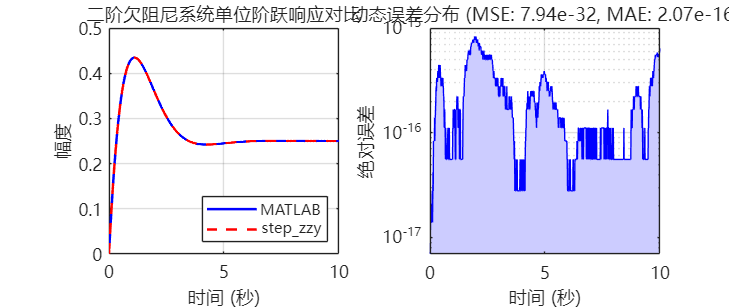


% 动态特性对比图
figure('Name','测试2: 二阶欠阻尼系统', 'Units','normalized','Position',[0.15 0.15 0.8 0.6]);

% 主响应曲线
subplot(1,2,1);
plot(t_matlab2, y_matlab2, 'b-', 'LineWidth', 1.5, 'DisplayName','MATLAB');
hold on;
plot(t_matlab2, y_zzy_interp2, 'r--', 'LineWidth', 1.5, 'DisplayName','step\_zzy');
ylabel('幅度', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title('二阶欠阻尼系统单位阶跃响应对比', 'FontName','Microsoft YaHei');
legend('FontName','Microsoft YaHei', 'Location','southeast');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei');

% 误差分布图
subplot(1,2,2);
area(t_matlab2, abs_error2, 'FaceColor',[0.8 0.8 1], 'EdgeColor','b');
ylabel('绝对误差', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title(sprintf('动态误差分布 (MSE: %.2e, MAE: %.2e)', mse2, mae2),...
      'FontName','Microsoft YaHei');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei', 'YScale','log');


%% 测试3: 非真分式系统（与您的 C 代码示例一致）
fprintf('========== 测试3: 非真分式系统 ==========\n');

========== 测试3: 非真分式系统 ==========


num3 = [1 3 2];
den3 = [1 4 3];  % G(s) = (s^2+3s+2)/(s^2+4s+3)

% MATLAB 内置函数
sys_matlab3 = tf(num3, den3);
t_sim3 = 0:0.01:5;
[y_matlab3, t_matlab3] = step(sys_matlab3, t_sim3);

% 自定义实现
sys_zzy3 = tf_zzy(num3, den3);
[y_zzy3, t_zzy3] = step_zzy(sys_zzy3, 5);

% 对齐到相同时间点
y_zzy_interp3 = interp1(t_zzy3, y_zzy3, t_matlab3, 'linear', 'extrap');

% 精度验证
abs_error3 = abs(y_matlab3 - y_zzy_interp3);
mse3 = mean(abs_error3.^2);
mae3 = mean(abs_error3);
max_error3 = max(abs_error3);

% 定位最大误差点
[~, idx_max3] = max(abs_error3);
fprintf('最大误差: %.2e (发生在 t=%.2f s)\n', max_error3, t_matlab3(idx_max3));

最大误差: 4.44e-16 (发生在 t=0.65 s)


fprintf('MSE: %.2e\n', mse3);

MSE: 2.27e-32


fprintf('MAE: %.2e\n', mae3);

MAE: 1.03e-16



% 初始瞬态区分析
idx_transient3 = t_matlab3 <= 0.5;
transient_error3 = abs_error3(idx_transient3);
fprintf('初始瞬态区(0-0.5s)最大误差: %.2e\n', max(transient_error3));

初始瞬态区(0-0.5s)最大误差: 2.22e-16



% 稳态区分析
idx_steady3 = t_matlab3 >= (max(t_matlab3)-1);
steady_error3 = abs_error3(idx_steady3);
fprintf('稳态区误差均值: %.2e\n\n', mean(steady_error3));

稳态区误差均值: 7.58e-17



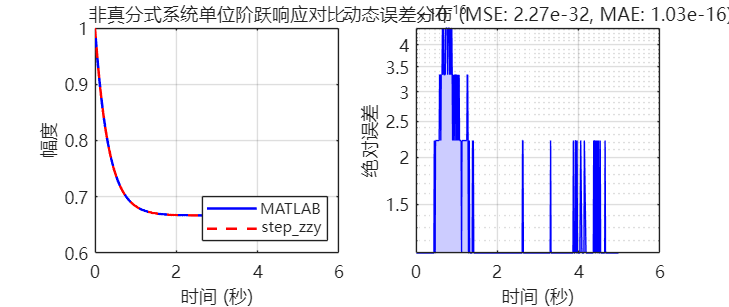


% 动态特性对比图
figure('Name','测试3: 非真分式系统', 'Units','normalized','Position',[0.2 0.2 0.8 0.6]);

% 主响应曲线
subplot(1,2,1);
plot(t_matlab3, y_matlab3, 'b-', 'LineWidth', 1.5, 'DisplayName','MATLAB');
hold on;
plot(t_matlab3, y_zzy_interp3, 'r--', 'LineWidth', 1.5, 'DisplayName','step\_zzy');
ylabel('幅度', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title('非真分式系统单位阶跃响应对比', 'FontName','Microsoft YaHei');
legend('FontName','Microsoft YaHei', 'Location','southeast');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei');

% 误差分布图
subplot(1,2,2);
area(t_matlab3, abs_error3, 'FaceColor',[0.8 0.8 1], 'EdgeColor','b');
ylabel('绝对误差', 'FontName','Microsoft YaHei');
xlabel('时间 (秒)', 'FontName','Microsoft YaHei');
title(sprintf('动态误差分布 (MSE: %.2e, MAE: %.2e)', mse3, mae3),...
      'FontName','Microsoft YaHei');
grid on;
set(gca, 'FontSize',10, 'FontName','Microsoft YaHei', 'YScale','log');


%% 总结
fprintf('========== 测试总结 ==========\n');

========== 测试总结 ==========


avg_mse = (mse1 + mse2 + mse3) / 3;
avg_mae = (mae1 + mae2 + mae3) / 3;

fprintf('平均 MSE: %.2e\n', avg_mse);

平均 MSE: 3.75e-32


fprintf('平均 MAE: %.2e\n', avg_mae);

平均 MAE: 1.29e-16


fprintf('平均一致小数位数: 约 %d 位\n', floor(-log10(avg_mae)));

平均一致小数位数: 约 15 位



if avg_mae < 1e-10
    fprintf('\n✓ 测试通过! 数值精度达到 10 位以上小数\n');
elseif avg_mae < 1e-6
    fprintf('\n✓ 测试通过! 数值精度达到 6 位以上小数\n');
elseif avg_mae < 1e-4
    fprintf('\n✓ 测试通过! 数值精度达到 4 位以上小数\n');
else
    fprintf('\n✗ 警告: 数值误差较大，需要检查实现\n');
end


✓ 测试通过! 数值精度达到 10 位以上小数



%% 稳态值验证
fprintf('\n========== 稳态值验证 ==========\n');


========== 稳态值验证 ==========


fprintf('测试1稳态值: MATLAB=%.6f, step_zzy=%.6f\n', y_matlab(end), y_zzy_interp(end));

测试1稳态值: MATLAB=0.499977, step_zzy=0.499977


fprintf('测试2稳态值: MATLAB=%.6f, step_zzy=%.6f\n', y_matlab2(end), y_zzy_interp2(end));

测试2稳态值: MATLAB=0.249991, step_zzy=0.249991


fprintf('测试3稳态值: MATLAB=%.6f, step_zzy=%.6f\n', y_matlab3(end), y_zzy_interp3(end));

测试3稳态值: MATLAB=0.666667, step_zzy=0.666667
